clear;clc;close('all');

% Define the folder path and filename
folderPath = 'C:\Users\user\OneDrive\桌面\物理\專題\Quantum_Optics\Simulation';
filename = 'rho_data.mat';

% Ensure the folder exists
if ~exist(folderPath, 'dir')
    mkdir(folderPath);
end

% Create the full file path
filepath = fullfile(folderPath, filename);

data = load(filepath);

% Constants
e = 1.60217662e-19;
a_0 = 5.29177211e-11;
h_bar = 1.054571817e-34;
E_a = -13.6 * e;
E_b = -3.4 * e;
w = (E_b - E_a) / h_bar

w = 1.5497e+16

nu = w

nu = 1.5497e+16

tdm = -128 * sqrt(2) / 243 * e * a_0

tdm = -6.3158e-30

I = 10^3; %Small:1 Medium:5 Large:9
eps0 = 8.854e-12;
c = 2.998e8;
E_field_amplitude = sqrt(2 * I / (eps0 * c))

E_field_amplitude = 868.0194


omega_R_0 = abs(tdm) * E_field_amplitude / h_bar

omega_R_0 = 5.1986e+07


% Time-independent Hamiltonian
H_0 = [E_a, 0; 0, E_b]

H_0 = 1.0e-17 *

   -0.2179         0
         0   -0.0545



%Decay rate
n = 1; % Refractive index of the medium (vacuum)
A_eg = (n * w^3) / (3 * pi * eps0 * h_bar * c^3) * abs(tdm)^2; % Spontaneous emission decay rate (s^-1)
global Gamma
Gamma = A_eg

Gamma = 6.2601e+08

Life_time = 1/Gamma

Life_time = 1.5974e-09


DDRatio = 1 % 0.7071

DDRatio = 1

global omega_R_0

omega_R_0 = DDRatio * Gamma

omega_R_0 = 6.2601e+08


% Initial state
Psi0 = [1/sqrt(2); 1/sqrt(2)];
Psi0 = [15/17;8/17];
Psi0 = [0.98; 0.198997487421];
Psi0 = [1;0];
%Psi0 = [0;1]; %excited
rho0 = Psi0 * Psi0'

rho0 =      1     0
     0     0



% Time evolution
global t;
t = linspace(0, 2e-8, 200);
dt = t(2)-t(1);

[omega_R, integral_omega_R] = rabi_frequency(t, omega_R_0);
fprintf('unit_pi_pulse = %6.4f',integral_omega_R);

unit_pi_pulse = 3.9979

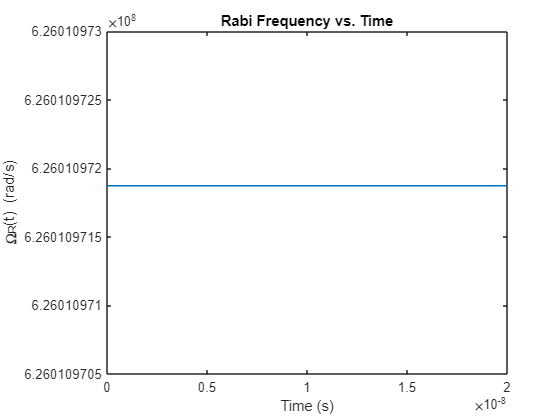

plot_rabi_frequency(t, rabi_frequency(t, omega_R_0));

options = odeset('RelTol', 1e-7, 'AbsTol', 1e-10, 'Stats','on');
[t, rho_vec] = ode45(@(t, rho_vec) lvneq(t, rho_vec, H_0, omega_R, nu, h_bar, Gamma), t, [rho0(1,1); rho0(1,2); rho0(2,1); rho0(2,2)], options);

1635 successful steps
1493 failed attempts
18769 function evaluations


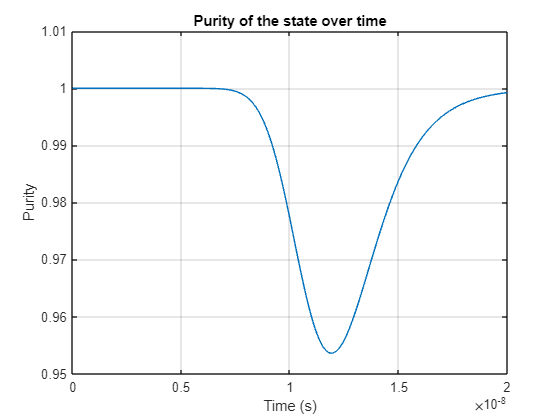

Minimum purity: 0.953585
Final purity: 0.999239



% Extract density matrix elements
rho11 = rho_vec(:, 1);
rho12 = rho_vec(:, 2);
rho21 = rho_vec(:, 3);
rho22 = rho_vec(:, 4);
plot_purity(t, rho11, rho12, rho21, rho22);

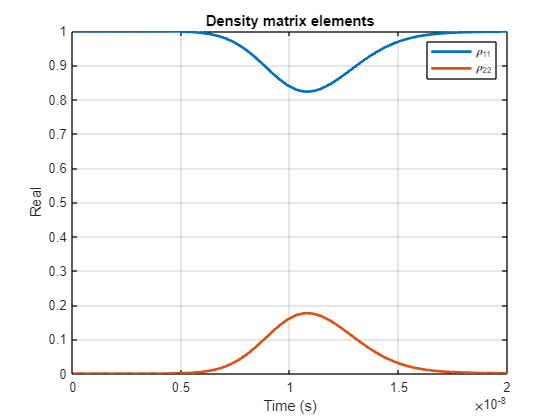

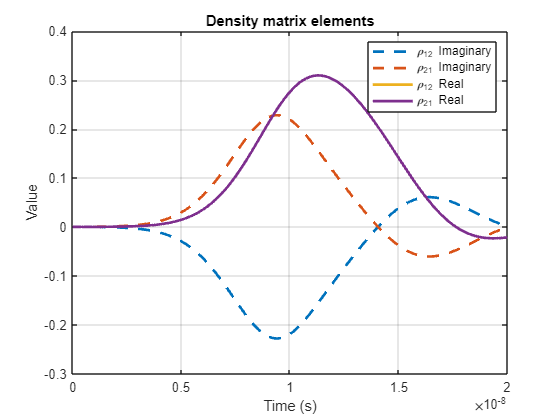

plot_population_rho(t, rho11, rho12, rho21, rho22);


%plot_density_matrix_3dbar_animation(t, rho11, rho12, rho21, rho22);
save_csv(t, rho11, rho12, rho21, rho22);

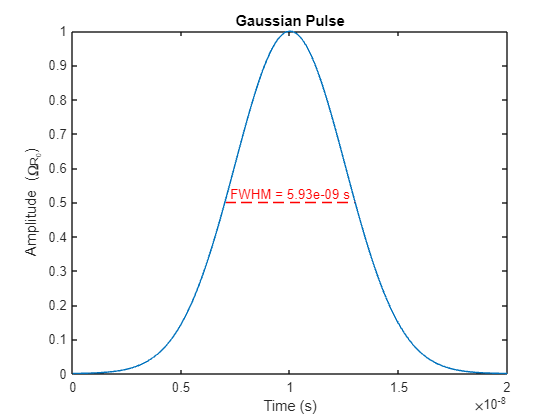

figure;
plot(t, gaussian_pulse(t));
title('Gaussian Pulse');
xlabel('Time (s)');
ylabel('Amplitude (\Omega_{R_0})');

% Find the maximum value of the pulse
[max_val, max_idx] = max(gaussian_pulse(t));

% Find the indices where the pulse is half the maximum value
half_max_indices = find(gaussian_pulse(t) >= max_val/2);

% Calculate FWHM in seconds
FWHM = t(half_max_indices(end)) - t(half_max_indices(1));

% Add a line and text to indicate FWHM on the plot
hold on;
plot([t(half_max_indices(1)), t(half_max_indices(end))], [max_val/2, max_val/2], 'r--');
text(mean(t(half_max_indices)), max_val/2, sprintf('FWHM = %.2e s', FWHM), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', 'Color', 'r');
hold off;

S_t = zeros(size(t));

for i = 1:length(t)
    rho_t = [rho11(i), rho12(i); rho21(i), rho22(i)];
    S_t(i) = von_neumann_entropy(rho_t);
end
figure;
plot(t, S_t);

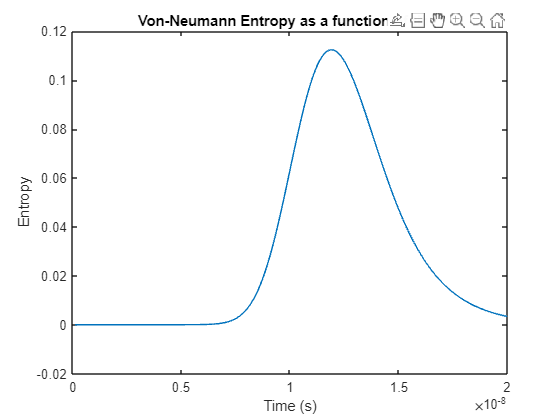

xlabel('Time (s)');
ylabel('Entropy');
title('Von-Neumann Entropy as a function of time');

% Propagation
x = linspace(0, 1e-3, 1000);
dx = x(2)-x(1);

%Spatial evolution constant
N_0 = 2.686e25 % 1 atm pressure and 0°C temperature

N_0 = 2.6860e+25

eta = w*N_0*(tdm^2)/(h_bar*eps0*c)

eta = 5.9313e+19

eta = 2 * pi*5 * 1000 * 10^8

eta = 3.1416e+12


omega_p = zeros(length(x),length(t));
rho_p11 = zeros(length(x),length(t));
rho_p12 = zeros(length(x),length(t));
rho_p21 = zeros(length(x),length(t));
rho_p22 = zeros(length(x),length(t));

omega_p(1,:) = omega_R;
rho_p11(1,:) = rho11;
rho_p12(1,:) = rho12;
rho_p21(1,:) = rho21;
rho_p22(1,:) = rho22;
rho_p11(:,1) = rho0(1,1);
rho_p12(:,1) = rho0(1,2);
rho_p21(:,1) = rho0(2,1);
rho_p22(:,1) = rho0(2,2);

for k=2:length(x)
    omega_p(k,:) = omega_p(k-1,:) + 1i * eta * rho_p21(k-1,:) * dx;
    
    options = odeset('RelTol', 1e-7, 'AbsTol', 1e-10);
    [t, rho_vec] = ode45(@(t, rho_vec) lvneq(t, rho_vec, H_0, omega_p(k,:), nu, h_bar, Gamma), t, [rho_p11(k,1); rho_p12(k,1); rho_p21(k,1); rho_p22(k,1)], options);
    rho_p11(k,:) = rho_vec(:, 1);
    rho_p12(k,:) = rho_vec(:, 2);
    rho_p21(k,:) = rho_vec(:, 3);
    rho_p22(k,:) = rho_vec(:, 4);

    disp(k);
end

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125

   126



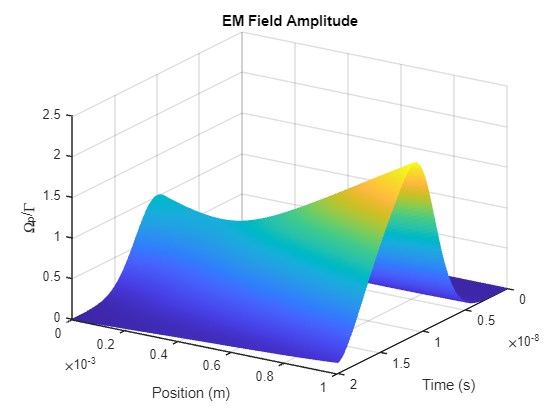

plot_omega_p(t, x, omega_p);

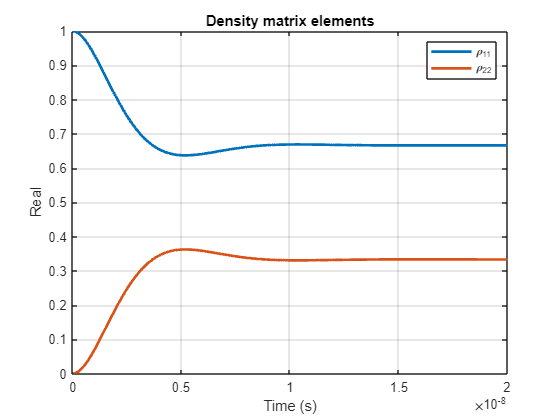

plot_rho21(t, x, rho_p21);

plot_w(t,x,rho_p11-rho_p22);

%plot(x,log(omega_p(:,end).^2/(omega_R_0^2)));

% Save the data in a .mat file
%save(filepath, 'omega_p', 'rho_p11', 'rho_p12', 'rho_p21', 'rho_p22');

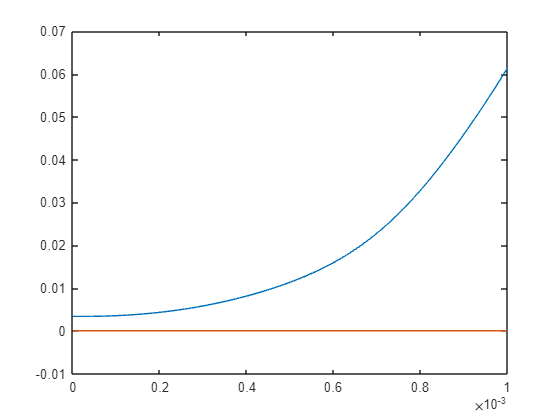

S_x = zeros(size(x));

for i = 1:length(x)
    rho_x = [rho_p11(i,end), rho_p12(i,end); rho_p21(i,end), rho_p22(i,end)];
    S_x(i) = von_neumann_entropy(rho_x);
end
figure;
plot(x, real(S_x),x, imag(S_x));

k = eta/Gamma % Replace with your desired value for k
r0 = omega_R_0/Gamma % Replace with your desired initial condition
% Solve the ODE using ode45
[~, r_sol] = ode45(@(x, r) ode_function(x, r, k), x, r0);

% Plot the solution
figure;
plot(x, r_sol);
xlabel('x');
ylabel('r(x)');
title('Solution of the ODE');


% Spatial EM Field Amplitude and Coherence within the medium
figure;
yyaxis left;
EM_Field_Amplitude = omega_p(:,end) / Gamma;
plot(x, EM_Field_Amplitude, 'LineWidth', 2);

xlabel('Position, x');
ylabel('EM Field Amplitude, $\Omega_p/\Gamma$', 'Interpreter', 'latex');

yyaxis right;
coherence = imag(rho_p21(:,end));
plot(x, coherence, 'LineWidth', 2);

[maxCoherence, maxIndex] = max(coherence);
hold on;
plot(x(maxIndex), maxCoherence, 'r.', 'MarkerSize', 20, 'LineWidth', 1.5);
hold off;

ylabel('Coherence, Im($\rho_{21}$)', 'Interpreter', 'latex');
title('Spatial EM Field Amplitude and Coherence within the Medium');

text(x(maxIndex), maxCoherence, ...
     sprintf('(%.3g, %.3g)', x(maxIndex), maxCoherence), ...
     'HorizontalAlignment', 'left', ...
     'VerticalAlignment', 'bottom', ...
     'Interpreter', 'latex', ...
     'FontSize', 10);

grid on;

function pulse = gaussian_pulse(t)
    % Gaussian Temporal Pulse
    tau = 6e-9; % Pulse duration (FWHM) in seconds
    t0= 1e-8;
    pulse = exp(-(4*log(2)*(t - t0).^2)/tau^2);
end

function [omega_R, integral_omega_R] = rabi_frequency(t, omega_R_0)
    % Rabi frequency
    omega_R = zeros(1, length(t))+omega_R_0;
    omega_R = omega_R_0 .* gaussian_pulse(t);

    % Calculate the integral of Rabi frequency
    integral_omega_R = trapz(t, omega_R);
end

% Liouville-von Neumann equation function
function drho_dt = lvneq(T, rho_vec, H_0, omega_R, nu, h_bar, Gamma)
    global t;
    % % Time-dependent part of H_1
    % H_1_t = [0, -h_bar*omega_R(max(find(t<=T))); -h_bar*conj(omega_R(max(find(t<=T)))), 0] * cos(nu * T);
    % 
    % % Total Hamiltonian
    % H_t = H_0 + H_1_t;
    
    global omega_R_0
    Nabla = omega_R_0;
    H_t = h_bar*[0, -0.5*omega_R(max(find(t<=T))); -0.5*conj(omega_R(max(find(t<=T)))), Nabla];

    drho_dt = zeros(4, 1);
    % Liouville-von Neumann equation
    drho_dt(1) = -1i / h_bar * (H_t(1,2)*rho_vec(3) - H_t(2,1)*rho_vec(2));
    drho_dt(2) = -1i / h_bar * (H_t(1,1)*rho_vec(2) + H_t(1,2)*rho_vec(4) - H_t(1,2)*rho_vec(1) - H_t(2,2)*rho_vec(2));
    drho_dt(3) = -1i / h_bar * (H_t(2,1)*rho_vec(1) + H_t(2,2)*rho_vec(3) - H_t(1,1)*rho_vec(3) - H_t(2,1)*rho_vec(4));
    drho_dt(4) = -1i / h_bar * (H_t(2,1)*rho_vec(2) - H_t(1,2)*rho_vec(3));

    % Spontaneous emission
    drho_dt = drho_dt + Gamma/2*[2*rho_vec(4); -1*rho_vec(2); -1*rho_vec(3); -2*rho_vec(4)];
end

function plot_rabi_frequency(t, omega_R)
    figure;
    plot(t, omega_R);
    xlabel('Time (s)');
    ylabel('\Omega_R(t) (rad/s)');
    title('Rabi Frequency vs. Time');
    hold off;
end

function plot_omega_p(t, x, omega_p)
    % Plot the real part of omega_p
    figure;
    mesh(t, x, real(omega_p));
    xlabel('Time (s)');
    ylabel('Position (m)');
    zlabel('Re(\Omega_p)');
    title('Real Part of \Omega_p');

    % Plot the imaginary part of omega_p
    figure;
    mesh(t, x, imag(omega_p));
    xlabel('Time (s)');
    ylabel('Position (m)');
    zlabel('Im(\Omega_p)');
    title('Imaginary Part of \Omega_p');

    % figure;
    % global Gamma;
    % mesh(t, x, abs(omega_p)/Gamma);
    % xlabel('Time (s)');
    % ylabel('Position (m)');
    % zlabel('Abs(\Omega_p)/Gamma');
    % title('Absolute value of \Omega_p');

    figure;
    global Gamma;
    mesh(t, x, abs(omega_p)/Gamma);
    xlabel('Time (s)');
    ylabel('Position (m)');
    zlabel('\Omega_p/\Gamma');
    title('EM Field Amplitude');
    view([122.55249 26.39368])
end

function plot_rho21(t, x, coh)
    figure;
    mesh(t, x, imag(coh));
    xlabel('Time (s)');
    ylabel('Position (m)');
    zlabel('\rho_{21}');
    title('Coherence');
    view([122.55249 26.39368])
end

function plot_w(t, x, w)
    figure;
    mesh(t, x, real(w));
    xlabel('Time (s)');
    ylabel('Position (m)');
    zlabel('\rho_{22}-\rho_{11}');
    title('Population Inversion');
    view([122.55249 26.39368])
end

function plot_purity(t, rho11, rho12, rho21, rho22)
    % Calculate the purity for each time point
    num_points = length(t);
    purity = zeros(num_points, 1);

    for i = 1:num_points
        rho = [rho11(i), rho12(i); rho21(i), rho22(i)];
        purity(i) = abs(trace(rho*rho));
    end

    % Plot the purity over time
    figure;
    plot(t, purity);
    xlabel('Time (s)');
    ylabel('Purity');
    title('Purity of the state over time');
    grid on;


    fprintf('Minimum purity: %.6f\n', min(purity));
    fprintf('Final purity: %.6f\n', purity(end));
end

% Plot density matrix elements
function plot_population_rho(t, rho11, rho12, rho21, rho22)
    figure;
    % Plot real parts
    plot(t, real(rho11), 'LineWidth', 2);
    hold on;
    plot(t, real(rho22), 'LineWidth', 2);

    global Gamma
    %plot(t, exp(-Gamma*t), '--','LineWidth', 1)
    hold off;
    xlabel('Time (s)');
    ylabel('Real');
    legend('\rho_{11}','\rho_{22}');
    title('Density matrix elements');
    grid on;

    figure;
    plot(t, imag(rho12), '--', 'LineWidth', 2);
    hold on;
    plot(t, imag(rho21), '--', 'LineWidth', 2);
    plot(t, real(rho12), 'LineWidth', 2);
    plot(t, real(rho21), 'LineWidth', 2);
    hold off;
    xlabel('Time (s)');
    ylabel('Value');
    legend('\rho_{12} Imaginary', '\rho_{21} Imaginary', '\rho_{12} Real', '\rho_{21} Real');
    title('Density matrix elements');
    grid on;

end

function plot_density_matrix_3dbar_animation(t, rho11, rho12, rho21, rho22)
    % Create a figure and set up the subplots
    figure;
    ax1 = subplot(1, 2, 1);
    ax2 = subplot(1, 2, 2);

    for i = 1:10:length(t)
        % Calculate the density matrix elements at the current time step
        real_matrix = real([rho11(i), rho12(i); rho21(i), rho22(i)]);
        imag_matrix = imag([rho11(i), rho12(i); rho21(i), rho22(i)]);

        % Plot the density matrix elements as 3D bar diagrams at the current time step
        subplot(1, 2, 1, ax1);
        cla(ax1); % Clear the current axes
        bar3(real_matrix);
        title(sprintf('Real part (t = %.2e s)', t(i)));
        xlabel('Column index');
        ylabel('Row index');
        zlabel('Real');
        
        % Set the z-axis limits for the real part
        zlim(ax1, [-1, 1]);

        % Add text labels
        text(0.75, 1, (real_matrix(1,1) >= 0)*(real_matrix(1,1) + 0.2) + (real_matrix(1,1) < 0)*0.1, '\rho_{11}', 'FontSize', 10, 'FontWeight', 'bold');
        text(1.75, 1, (real_matrix(1,2) >= 0)*(real_matrix(1,2) + 0.2) + (real_matrix(1,2) < 0)*0.1, '\rho_{12}', 'FontSize', 10, 'FontWeight', 'bold');
        text(0.75, 2, (real_matrix(2,1) >= 0)*(real_matrix(2,1) + 0.2) + (real_matrix(2,1) < 0)*0.1, '\rho_{21}', 'FontSize', 10, 'FontWeight', 'bold');
        text(1.75, 2, (real_matrix(2,2) >= 0)*(real_matrix(2,2) + 0.2) + (real_matrix(2,2) < 0)*0.1, '\rho_{22}', 'FontSize', 10, 'FontWeight', 'bold');

        subplot(1, 2, 2, ax2);
        cla(ax2); % Clear the current axes
        bar3(imag_matrix);
        title(sprintf('Imaginary part (t = %.2e s)', t(i)));
        xlabel('Column index');
        ylabel('Row index');
        zlabel('Imaginary');
        
        % Set the z-axis limits for the imaginary part
        zlim(ax2, [-1, 1]);

        % Add text labels
        text(0.75, 1, (imag_matrix(1,1) >= 0)*(imag_matrix(1,1) + 0.2) + (imag_matrix(1,1) < 0)*0.1, '\rho_{11}', 'FontSize', 10, 'FontWeight', 'bold');
        text(1.75, 1, (imag_matrix(1,2) >= 0)*(imag_matrix(1,2) + 0.2) + (imag_matrix(1,2) < 0)*0.1, '\rho_{12}', 'FontSize', 10, 'FontWeight', 'bold');
        text(0.75, 2, (imag_matrix(2,1) >= 0)*(imag_matrix(2,1) + 0.2) + (imag_matrix(2,1) < 0)*0.1, '\rho_{21}', 'FontSize', 10, 'FontWeight', 'bold');
        text(1.75, 2, (imag_matrix(2,2) >= 0)*(imag_matrix(2,2) + 0.2) + (imag_matrix(2,2) < 0)*0.1, '\rho_{22}', 'FontSize', 10, 'FontWeight', 'bold');

        % Update the plot and pause for a short duration
        hold on;
        pause(0.1);
        hold off;
    end

    % Adjust the position of the subplots to avoid overlap
    ax1.Position = [0.1 0.1 0.35 0.8];
    ax2.Position = [0.55 0.1 0.35 0.8];
end

function save_csv(t, rho11, rho12, rho21, rho22)
    folderPath = 'C:\Users\user\OneDrive\桌面\物理\專題\Quantum_Optics\Simulation';
    filename = 'rho_data.csv';
    filepath = fullfile(folderPath, filename);

    rho_data = [t, rho11, rho12, rho21, rho22];
    csvwrite(filepath, rho_data);
end

function S = von_neumann_entropy(rho_f)
    eigenvalues = eig(rho_f);
    S = -sum(eigenvalues .* log(eigenvalues));
end

function drdx = ode_function(x, r, k)
    drdx = -k * r / (1 + 2 * r^2);
end